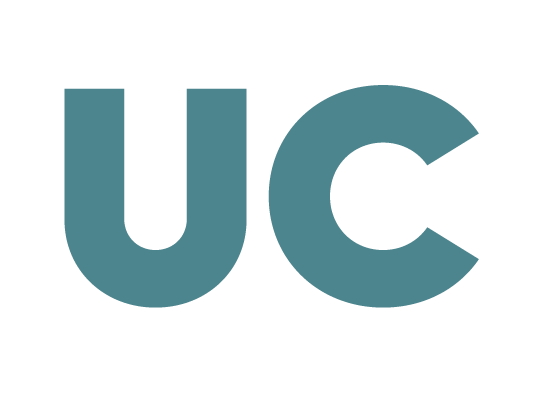

***Grado de Tecnologías de Telecomunicación***

**G282: Álgebra y Geometría**

# **Práctica 8: Proyección ortogonal**

*Dpto. Matemática Aplicada y Ciencias de la Computación*

**Objetivos**

- Calcular y utilizar la matriz de proyección sobre un cierto subespacio

## **Proyección de un vector sobre un subespacio**

Para calcular la proyección de un vector sobre un subespacio *S*  de $\mathbb{R}^n$hemos visto dos estrategias distintas:

- Método 1: Dada una **base ortogonal** de *S, *{u1,u2, ..., up}  podemos calcular la proyección con la fórmula: $\text{proy}_\mathbf{S} (\vec{v}) = \text{proy}_{<\vec{u}_1>} (\vec{v}) + \text{proy}_{<\vec{u}_2>} (\vec{v}) + \dots + \text{proy}_{<\vec{u}_p>} (\vec{v})
$. Si no disponemos de una base ortogonal de S podemos utilizar cualquiera de los procedimientos para ortogonalizar bases vistos en la práctica anterior y seguidamente aplicar la fórmula.

- Método 2: Podemos calcular el vector proyección sobre *S* a partir de la **matriz de proyección** $P_S$ , como la transformación lineal   $proy_{S}(\vec{v})=P_S\vec{v}$

El uso de la matriz de proyección es más sencillo de implementar con MATLAB, mientras que sin ordenador el Método 1 suele ser menos costoso.

### **Matriz de proyección**

La matriz de proyección sobre un subespacio $S$ de $\mathbb{R}^n$se obtiene como $P_S=B_S(B_{S}^{t}B_S)^_{-1}B_{S}^t$, donde $B_S$ es una matriz que contiene en sus columnas los vectores de una base (cualquiera, no tiene por qué ser ortogonal/ortonormal) de $S$. Por tanto, para hallar la matriz de proyección sobre un subespacio $S = <(2,-1,1), (-1,2,1)>$ de $\mathbb{R}^3$:

baseS = [2 -1 1; -1 2 1]';   % base de S (es un sist. gen. y los vectores son l.i.). 
dot(baseS(:,1), baseS(:,2))  % vemos que esta base NO es ortogonal
PS = baseS*inv(baseS'*baseS)*baseS'  % matriz de proyección sobre S

En el caso de que $B_S$ sea **base ortonormal** el cálculo de la matriz de proyección se simplifica a $P_S=B_{So}B_{So}^t$(por ser ortonormal $B_{S}^{t}B_S=I$). Recuerda que para ortonormalizar los vectores de una base podemos usar la función *orth*. Para no tener que memorizar la matriz de proyección, a partir de ahora, siempre que utilicemos MATLAB obtendremos la matriz de proyección ortonormalizando los vectores de la base previamente.

El orden de la matriz de proyección $P_S$ (recuerda que $P_S$ es siempre cuadrada) corresponde con la dimensión *n *del espacio vectorial al que pertenece el subespacio sobre el que proyectamos, en este caso es 3, por tratarse de $\mathbb{R}^3$. Además es una matriz simétrica. 

Una vez obtenida $P_S$ podemos obtener la proyección del vector $\vec{v}$ sobre $S$ como $proy_{S}(\vec{v})=P_S\vec{v}$ Por ejemplo, para proyectar ortogonalmente el vector $(3,4,5)$ sobre $S$:

v = [3 4 5]';    % vector a proyectar
proy_S_v = PS*v  % proyección de v sobre S

Además, otra caracteristica interesante de la matriz de proyección $P_S$ es que los vectores de sus columnas forman un sistema generador de $S$. ¿Qué rango deberá tener por tanto $P_S$ ?

rank(PS)

## Ejercicios propuestos

**Ejercicio 1:**

En $\mathbb{R}^3$, proyecta ortogonalmente el vector $\vec{v} = (3,2,2)$ sobre el subespacio $S=<(2,0,1),(0,3,-1),(2,3,0)>$ utilizando la matriz de proyección. Calcula dicha matriz partiendo de dos bases de $S$ distintas, una de ellas ortonormal y la otra no. ¿Qué sucede?

**Ejercicio 2:**

Utilizando matrices de proyección, calcula la proyección ortogonal del vector $$\vec{v} = (3, 4, 5)$$ sobre el subpespacio $S : \lbrace x-y+z=0 \rbrace$ de $\mathbb{R}^3$ y sobre $S^\perp$. Comprueba que ambas proyecciones son ortogonales entre sí y que $\vec{v}$ puede expresarse como la suma de ambas. ¿Qué pasa si sumas la matriz de proyección sobre $S$ y la matriz de proyección sobre $S^\perp$? ¿Cual es la distancia entre el vector $$\vec{v}$$ y el subespacio *S?.*